# Skin Lesion Classification via CNN Transfer Learning

Last updated: October 7, 2021

## Load dataset

dataLocation = "Dataset/ISIC_2019_Training_Input"; % Relative path to folder where the .jpg files are located
labelsLocation = "Dataset/groundtruth_categorical.csv"; % Relative path to the categorical labels .csv file af

#### Create a datastore for the raw images. 

An image datastore is an object type which stores lists of file locations/names rather than the files themselves. Since we are working with a ~10GB dataset, this is almost necessary. 

See [imageDatstore](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) in the MATLAB docs for more info. 

image_datastore = imageDatastore(dataLocation); % Initialize the imageDatastore with the files in the dataLocation

Error using imageDatastore (line 139)
Cannot find files or folders matching: 'Dataset/ISIC_2019_Training_Input'.

num_images = length(image_datastore.Files);

#### Convert ground truth labels to categorical

If you have downloaded the labels from the [ISIC website](https://challenge.isic-archive.com/data), they will be in a table form where the first column is the image file name. 

The remaining columns (2-9) represent a logical matrix where each column represents one of our labels. Each row has exactly one column that equals 1, denoting which diagnosis that image has been labeled.

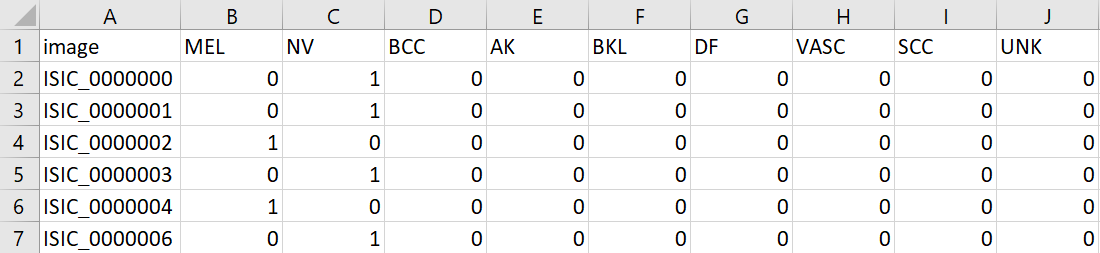

When assigning labels to an imageDatastore, we must supply them in a one-dimensional vector. Hence, we should collapse each logical row in the matrix to a single string that is the image's label. 

To avoid doing this every time this script is run, we have provided a helper script called [convertTruthLabels.mlx](matlab:open('./convertTruthLabels.mlx')) that converts the .csv file from the ISIC datset into a new .csv with the desired format. If you have not done so, please run that script now. 

**labelsLocations** should be set to the path of this converted file.

#### Import ground truth labels

groundtruth = readtable(labelsLocation); % Read the converted .csv file as a table
image_datastore.Labels = categorical(groundtruth.category); % Set the Labels of the imageDatastore to a categorical type array from the category column of .csv

Display some images with their true label

for i = 1:6
    subplot(2,3,i);
    sample_idx = randi(num_images);
    imshow(readimage(image_datastore, sample_idx)); % Extract the image file from the imageDatastore and imshow it
    title(image_datastore.Labels(sample_idx));
end
subplot();


## Prepare dataset for model training

#### Split dataset into training set, validation set

MATLAB provides the [splitEachLabel](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) to split an imageDatastore into training and validation (and test) sets. This works by taking images proportionally from each category, so each set has the same distribution of classification labels. 

[trainImds, valImds] = splitEachLabel(image_datastore, 0.8, 'randomized'); % Randomly select 80% of each label into a new train set imageDatastore, the rest goes into validation

### Balance training set by oversampling underrepresented classes

As shown below, the ISIC dataset is highly imbalanced. 

Of our 8 classes, ~50% are of label 'Melanocytic nevus' (medical term for the common birthmark), ~18% are of label 'Melanoma'. Furthermore, our 4 smallest classes account for less than 8% of the total dataset combined. This is a problem as our model will heavily prefer to predict the larger classes purely by statistical likeliness. 

trainingLabelCounts = countEachLabel(trainImds) % Get the number of images that belong to each class label

To address this issue, we ***oversample*** the dataset - create duplicate entries for each image in the smaller classes to make up the difference in size. We have provided a separate helper function [oversampleDataset.m](matlab:open('./oversampleDataset.m')) to do this, and return the balanced imageDatastore.

targetLabelCount = max(trainingLabelCounts.Count); % the ceiling for oversampleDataset to duplicate each class label to
balTrainImds = oversampleDataset(trainImds, targetLabelCount);


Each category should have the same number of samples as the highest category (Mel. nevus). 

labelCounts = countEachLabel(balTrainImds) 

#### Augment training images (and resize images to work with GoogLeNet)

Since we are performing transfer learning with GoogLeNet CNN, we must resize each image to fit the input layer size (224x224). 

inputSize = [224,224];

GoogLeNet is a deep CNN with many nodes. Being so complex, it will easily overfit to our training set. To mitigate this, one step we take is to "augment" our image samples.

These augmentations include flipping the images vertically and horizontally, rotating them around their center, zooming in/out slightly, and adding shear/skew to the images. 

To resize and augment our training set, we create an [augmentedImageDatastore](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) by passing the desired image size, the imageDatastore, and an [imageDataAugmenter](https://www.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html) that is configured with the augmentation settings.

% Create the imageDataAugmenter with the desired augmentation effects.
% These effects are each applied at random.
% See the docs for in-depth descriptions of each Name, Value option pair. 
augmenter = imageDataAugmenter( ...
    "RandXReflection", true, ... 
    "RandYReflection", true, ...
    "RandRotation", [-180 180], ... % Rotate an image between +-180 degrees
    "RandScale", [0.8 1.5], ...     % Scale an image from 80% to 150% of its original size
    "RandXShear", [0 30], ...       % Shear an image horizontally and vertically within the range 0 degrees to 30 degrees
    "RandYShear", [0 30]);          


% Augment the training set with the determined inputSize and imageDataAugmenter
% Returned is a new type of object - augmentedImageDatastore
trainds = augmentedImageDatastore(inputSize, balTrainImds,"DataAugmentation",augmenter);

% Preview some of the augmented images
minibatch = preview(trainds);
imshow(imtile(minibatch.input));

#### Resize the validation set

Any image going through the GoogLeNet model needs to be 224x224, so we should resize the validation set as well. 

valds = augmentedImageDatastore([224,224], valImds);

## Import and modify pretrained Neural Network

To make GoogLeNet compatible with our training data, we change the last two layers to output classifications for our 8 labels. 

Import GoogLeNet

net = googlenet; % Import the googlenet DAGNet object from the Deep Learning Toolbox
lgraph = layerGraph(net); % Convert to a layerGraph object, which contains all the data for each layer of the Neural Network

Replace the final fullyConnectedLayer

newFc = fullyConnectedLayer(numel(labelCounts.Label),"Name","new_fc"); % Create a new fullyConnectedLayer with nodes for each class 
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc); % Replace the existing fullyConnectedLayer

#### Implement weighted cross-entropy loss to address imbalanced dataset

If for some reason we do not oversample the training set, we avoid the aforementioned bias for larger classes by using weighted cross-entropy loss.

Essentially, the model is given a penalty for choosing one of the larger classes as its prediction. This penalty/weight is determined by the classes proportion of the total labelCount. 

classWeights = max(labelCounts.Count)* ones(1,numel(labelCounts.Label)) ./ labelCounts.Count'

Replace the classificationLayer

% Create a new classificationLayer with our class Labels and cross-entropy weights
newOut = classificationLayer("Name","new_out", "ClassWeights", classWeights, "Classes", labelCounts.Label); 
lgraph = replaceLayer(lgraph,"output",newOut); % Replace the existing classificationLayer

## Set training options

We will be using MiniBatch Gradient Descent with Momentum. Learn more about neural network training algorithms [here.](https://ruder.io/optimizing-gradient-descent/)

The other training options (known as hyperparameters) such as Learning Rate and Minibatch size are created and passed into the trainNetwork function. 

- Minibatch size - How many images are fed-foward before each weight adjustment step. Largely determined by the amount of available dedicated Video RAM.

- Learning Rate - How large each weight adjustment step is. Smaller is slower, but too large can lead to divergence from the optimal value. 

- L2Regularization - Penalizes neural network nodes with large weights, so that any one node won't have a large effect on the output. Reduces overfitting.

We also implement early stopping. At regular intervals throughout training, the model is tested against the validation set. When the average classification loss on the validation set stops improving, training stops andthe model that performed best on the validation set is saved. 

miniBatchSize = 64;

validationsPerEpoch = 5;
validationPatienceEpochs = 3;

iterationsPerEpoch = floor(numel(trainds.Files)/miniBatchSize);
validationFrequency = floor(iterationsPerEpoch/validationsPerEpoch);
validationPatience = validationsPerEpoch * validationPatienceEpochs;

options = trainingOptions("sgdm", ...
    "InitialLearnRate", 0.001, ...
    'MiniBatchSize',miniBatchSize,"Shuffle", "every-epoch", ...
    'MaxEpochs', 30, ...
    'Plots','training-progress',"L2Regularization", 1e-4, ... 
    "ValidationData", valds, "ValidationFrequency",validationFrequency, ...
    "OutputNetwork","best-validation-loss", "ValidationPatience", validationPatience);

### Train the neural network

lesionNet = trainNetwork(trainds, lgraph, options);

#### Save trained model to device. 

Including the imageDatastores allows for proper re-evaluation of the model, since the training-validation split is randomized every time the script is run. 

save lesionNet_prev.mat lesionNet options balTrainImds valImds trainds valds;

#### Evaluate network on Validation set

preds = classify(lesionNet, valds);
valTrue = valImds.Labels;
valAccuracy = nnz(preds == valTrue)/numel(preds)
confusionchart(valTrue, preds, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized','Title',"Validation Set - Accuracy: " + string(valAccuracy));

### Visualize failed predictions

failedPredictions = find(preds~=valTrue);
num_fail = numel(failedPredictions);
failedSample = 247;
if ~isempty(failedPredictions)
    imshow(readimage(valImds,failedPredictions(failedSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(failedPredictions(failedSample))) + "// Predicted: " + string(preds(failedPredictions(failedSample))))
end

### Visualize correct predictions

correctPredictions = find(preds==valTrue);
num_correct = numel(correctPredictions);
correctSample = 666;
if ~isempty(correctPredictions)
    imshow(readimage(valImds,correctPredictions(correctSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(correctPredictions(correctSample))) + "// Predicted: " + string(preds(correctPredictions(correctSample))))
end

### Calculating Precision, 

mat = [	134	21	6	1	2	3	6	0
        30	579	15	4	23	11	2	1
        27	23	375	5	47	36	12	0
        0	6	1	38	1	1	1	0
        8	59	68	11	2225	198	2	4
        9	38	46	3	183	620	5	0
        13	18	9	2	0	2	82	0
        0	0	1	0	3	0	0	47 ]; %%replace mat with confusion matrix after.
precisionVector = zeros(1,8);
recallVector = zeros(1,8);
f1ScoreVector = zeros(1,8);
for ii= 1:1:8
   sumofColumn = sum(mat);
   precision = mat(ii,ii)/sumofColumn(ii); %formula for precision 
   precisionVector(ii) = precision;
   
   sumofRow = sum(mat,2);
   recall = mat(ii,ii)/sumofRow(ii); %formula for 
   recallVector(ii) = recall;
 
   f1Score = 2*(precisionVector(ii)*recallVector(ii))/(precisionVector(ii)+recallVector(ii)) ;
   f1ScoreVector(ii) = f1Score;
end
display(precisionVector)
display(recallVector)
display(f1ScoreVector)
disp_precision = array2table(precisionVector);
disp_precision.Properties.VariableNames(1:8) = {'Actinic keratosis', 'Basal cell carcinoma', 'Benign keratosis', 'Dermatofibroma', 'Melanocytic nevus', 'Melanoma', 'Squamous cell carcinoma', 'Vascular lesion'}
disp_recall = array2table(recallVector);
disp_recall.Properties.VariableNames(1:8) = {'Actinic keratosis', 'Basal cell carcinoma', 'Benign keratosis', 'Dermatofibroma', 'Melanocytic nevus', 'Melanoma', 'Squamous cell carcinoma', 'Vascular lesion'}
disp_f1 = array2table(f1ScoreVector);
disp_f1.Properties.VariableNames(1:8) = {'Actinic keratosis', 'Basal cell carcinoma', 'Benign keratosis', 'Dermatofibroma', 'Melanocytic nevus', 'Melanoma', 'Squamous cell carcinoma', 'Vascular lesion'}